This uses the simple propagator, implementing a periapsis burn.

First we define the satellite's characteristics. Approximately a 9U cubesat.

area = 1;       % m2
ref = 1.5;      % NA
initMass = 10;  % kg
endMass = 8;    % kg
isp = 2000;     % s
g0 = 9.80665;   % m/s2
exhVel = isp * g0;
thrust = 0.001;   % N
mDot = thrust / exhVel;
burnOverride = 1;

And the orbit's intial conditions. The model needs the semimajor axis, so we add Earth's radius.

earthRadius = 6378136.3;    % m
% [sma,ecc,inc,RAAN,aop,true_an] = deal(10000e3+earthRadius, 0.4, 0, 180, 135, -20); % elliptic
% [sma,ecc,inc,RAAN,aop,true_an] = deal(400e3+earthRadius, 0.01, 30, 0, 135, -20); % fairly circular
p = 800e3+earthRadius; f = 42000e3+earthRadius; sma = (p+f)/2; ecc = (f-p)/(f+p);
[inc,RAAN,aop,true_an] = deal(30, 0, 135, -20);
startDate = juliandate(datetime('today'));

If `burnOverride` is set to 0, we can specify the maneouvre strategy. We will only allow the satellite to burn at periapsis to make use of the Oberth effect.

% thrustingThreshold = sma*(1-ecc)+1000e3;
thrustingThreshold = sma*(1-ecc)*1.01;
% thrustingThreshold = 100e3+earthRadius;

Now choose a simulation length and run it.

tf = 12; tf = tf * 30 * 24 * 3600;
% open_system('propagatorSimple.slx');
tic;
simOut = sim('propagatorSimple.slx');


Build Summary

0 of 1 models built (1 models already up to date)
Build duration: 0h 0m 1.054s


toc

Elapsed time is 3.881643 seconds.


We extract the data from the simulation. This being the satellite's position and its attitude, and the Moon's position in order to obtain a trajectory line.

tsSat = simOut.yout{1}.Values;
ttSat = timeseries2timetable(tsSat);
tsSatAtt = simOut.yout{3}.Values;
ttSatAtt = timeseries2timetable(tsSatAtt);
tsMoon = simOut.yout{5}.Values;
ttMoon = timeseries2timetable(tsMoon);

To avoid conflicts with the viewer's trajectory interpolation, we retime the timetables manually (this is needed as of R2023b, but may be fixed in future updates).

ttSat = retime(ttSat,'minutely');
ttSatAtt = retime(ttSatAtt,'minutely');
ttMoon = retime(ttMoon,'minutely');

Raw plot

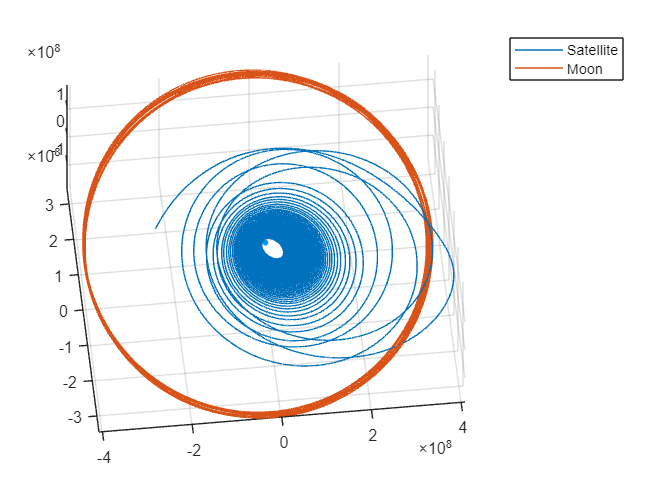

tic
figure
[X,Y,Z] = sphere();
p = surf(X*earthRadius, Y*earthRadius, Z*earthRadius); % plot Earth at the centre
set(p, 'edgecolor', 'none', 'FaceColor', [0,150,255]./255, 'HandleVisibility', 'off')
hold on
plot3(ttSat.Data(:,1), ttSat.Data(:,2), ttSat.Data(:,3), DisplayName='Satellite')
plot3(ttMoon.Data(:,1), ttMoon.Data(:,2), ttMoon.Data(:,3), DisplayName='Moon')
legend
axis equal
daspect([1 1 1])
view([-6 52])

lim = [-8 8]*1e8;
% xlim(lim)
% ylim(lim)
% zlim(lim)
toc

Elapsed time is 0.147427 seconds.
